## Cell Length - scatter cross section

% adding cross section to 3D scatter
global plot_range thickness i_cells;
data_set = "data_4";
switch data_set
    case 'data_4'
        plot_range = [-100 100 -100 100 0 35];
        num_sim = 1;
        num_files = 118;
    case 'data_20'
        plot_range = [-50 50 -50 50 0 35];
        num_sim = 20;
        num_files = 58;
    case 'data_adder'
        plot_range = [-150 150 -150 150 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_12_07_21'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_12_07_21_2'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_12_07_21_3'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_13_07_21_1'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_13_07_21_2'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'adder_length_1'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
end

filepath = '~/Desktop/test' ;   % mention your path 
myfolder = 'myfolder' ;   % new folder name 
folder = mkdir([filepath,filesep,myfolder]) ;

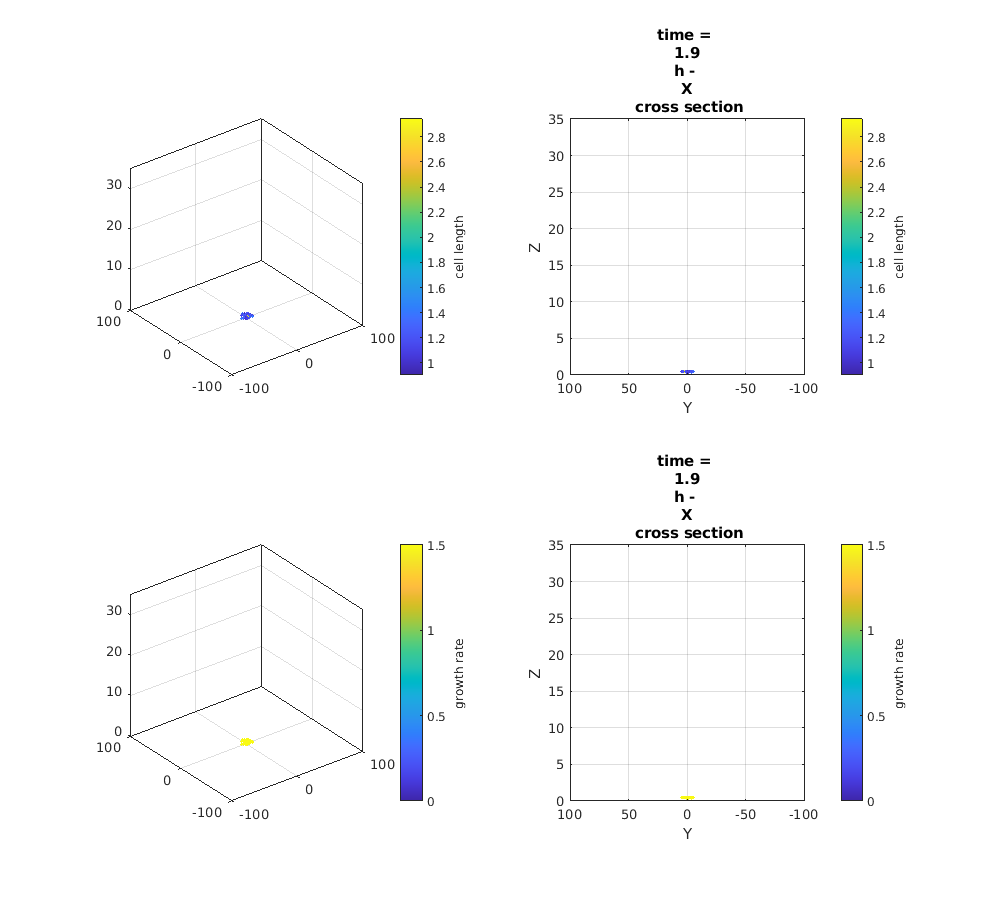

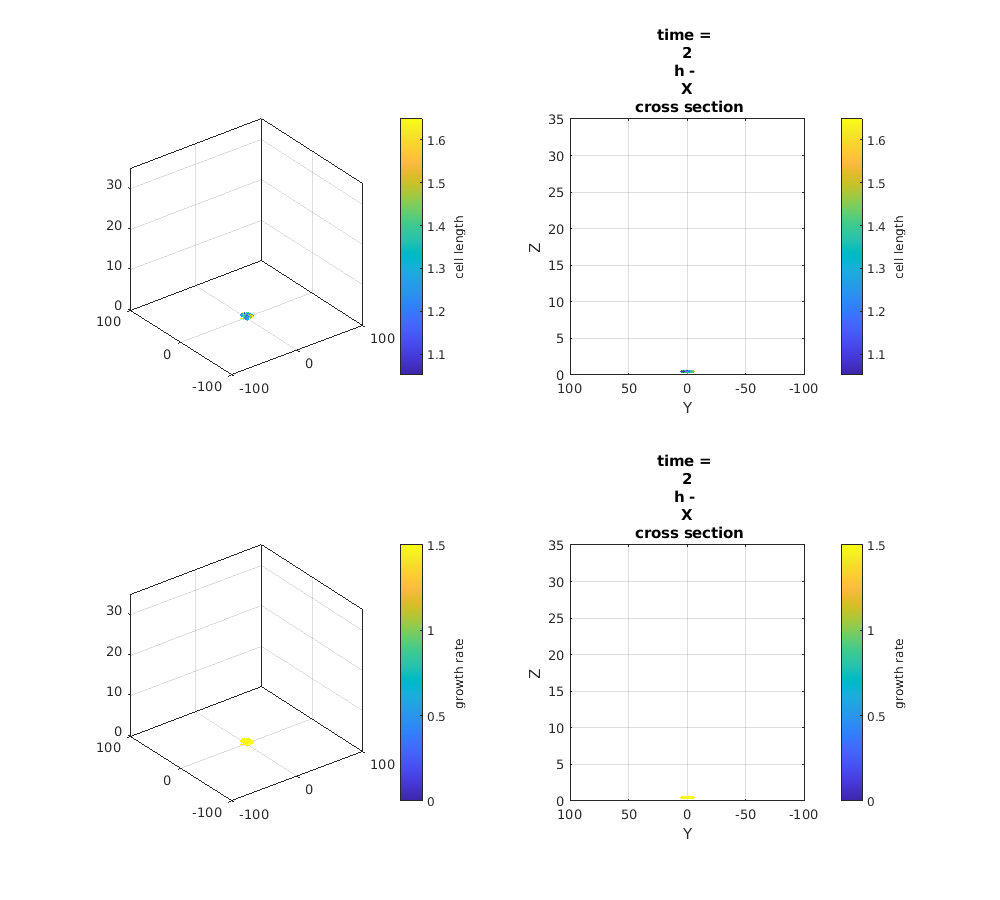

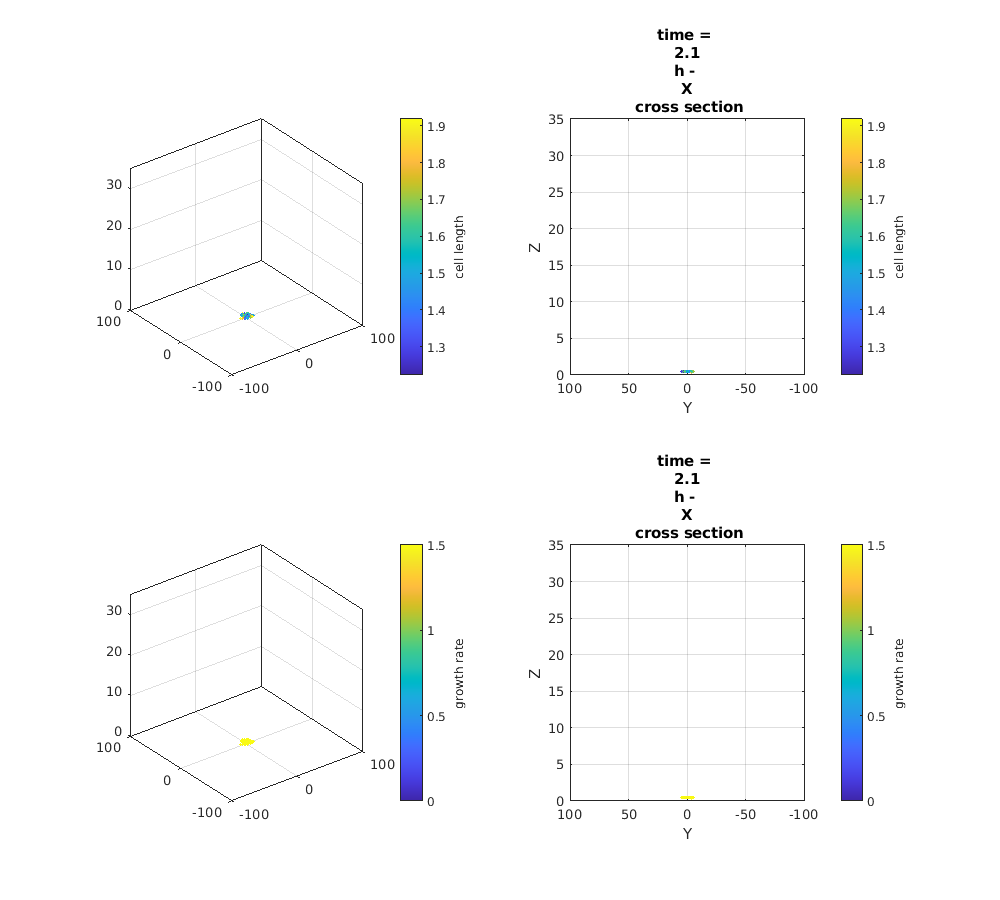

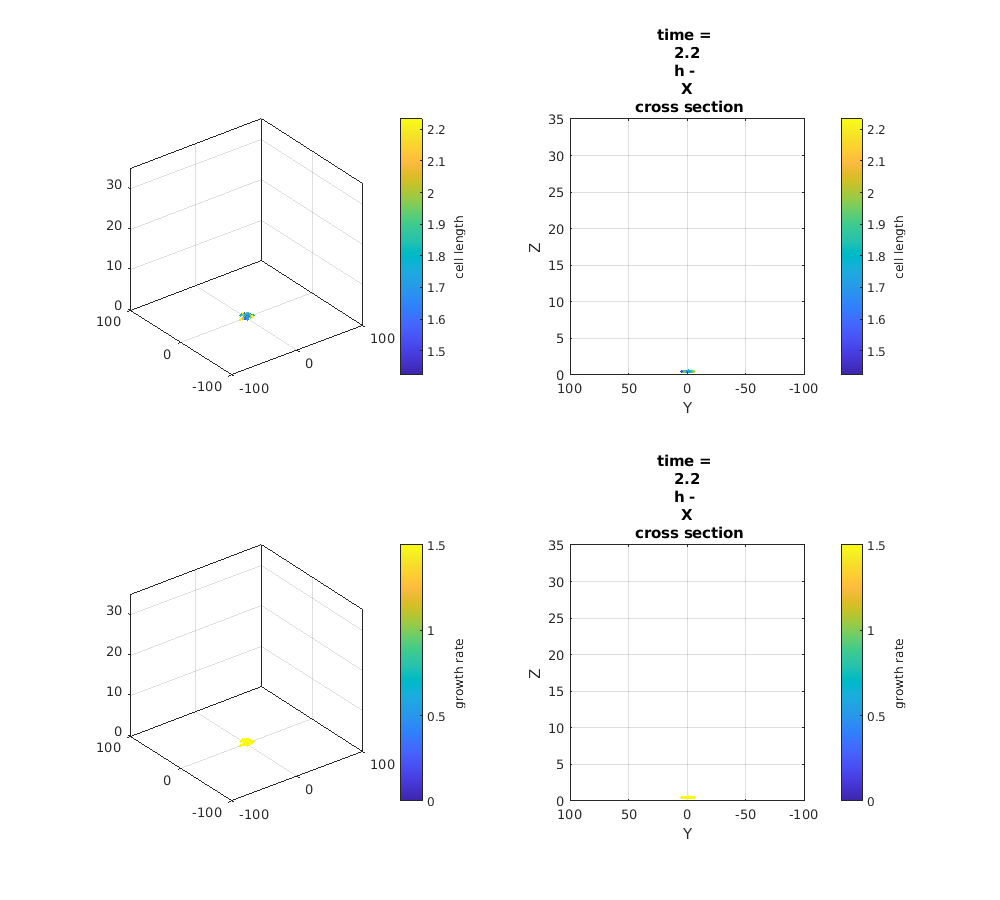

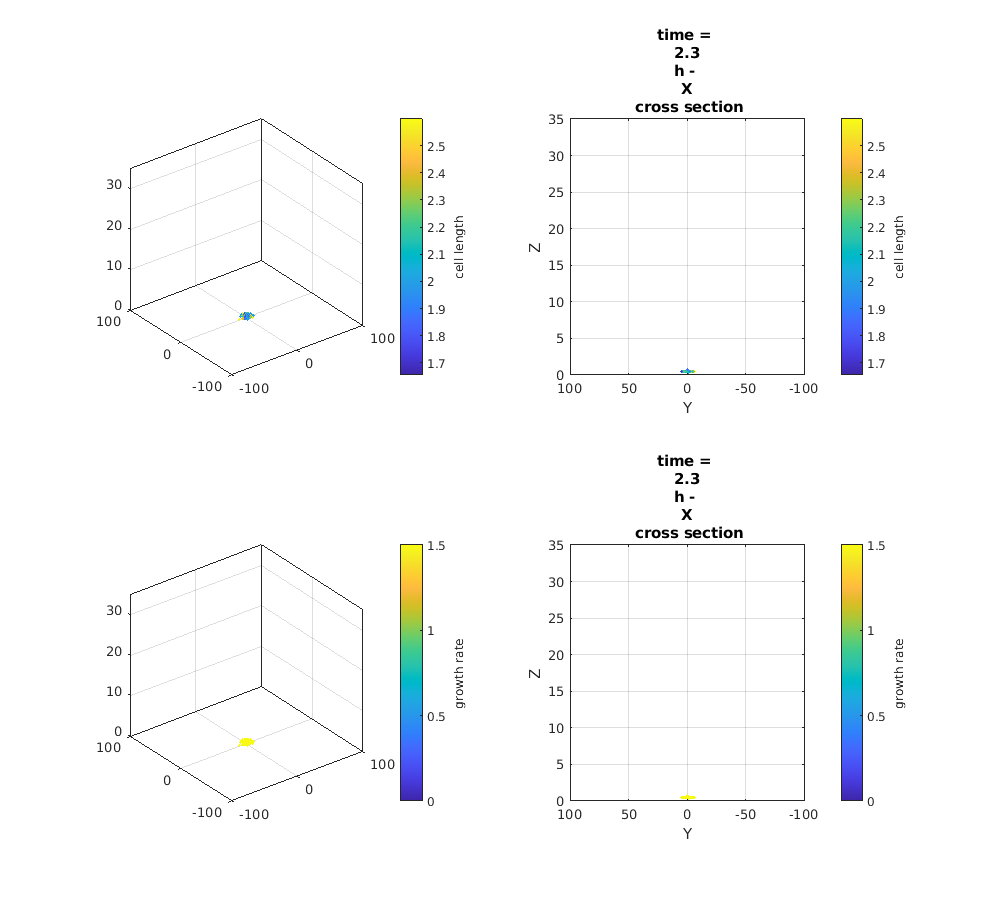

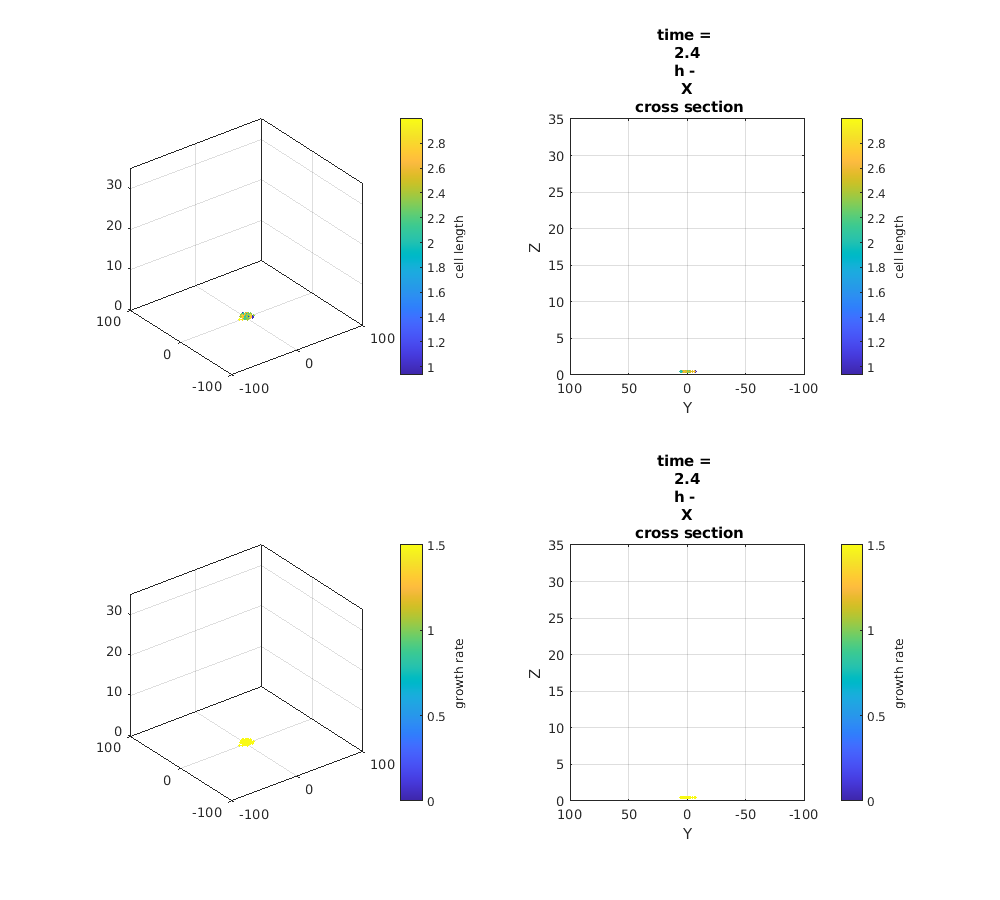

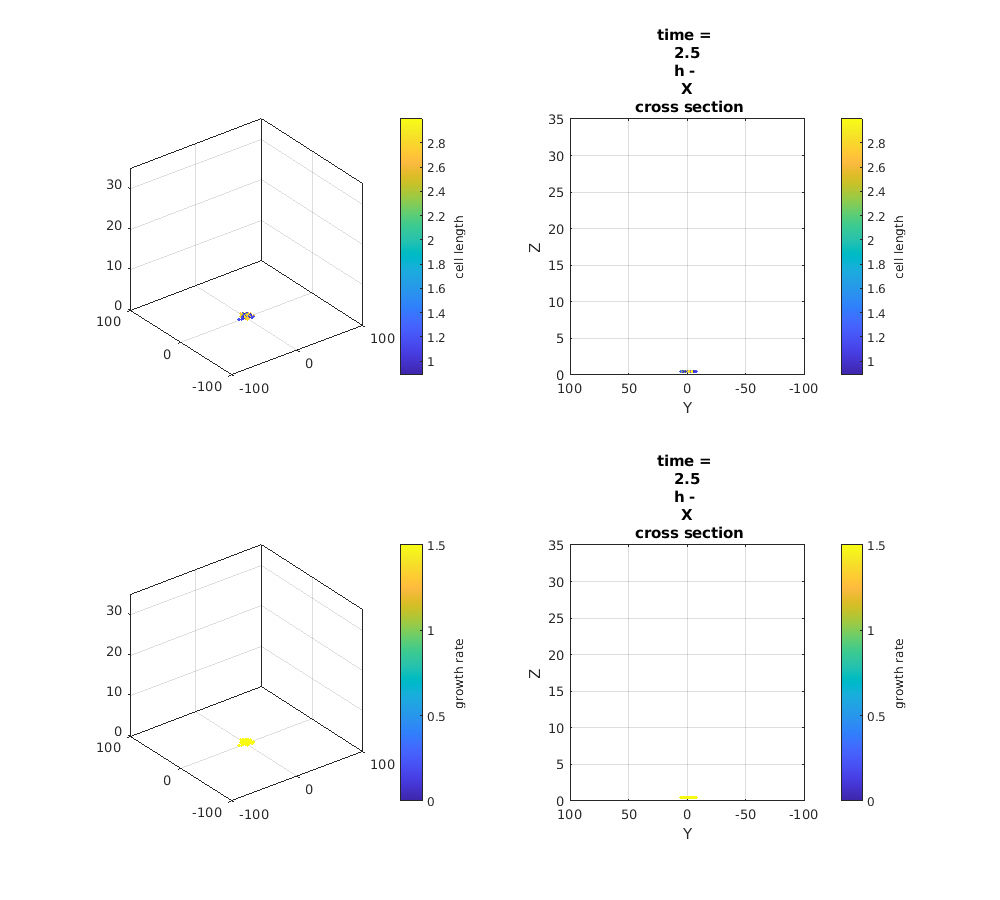

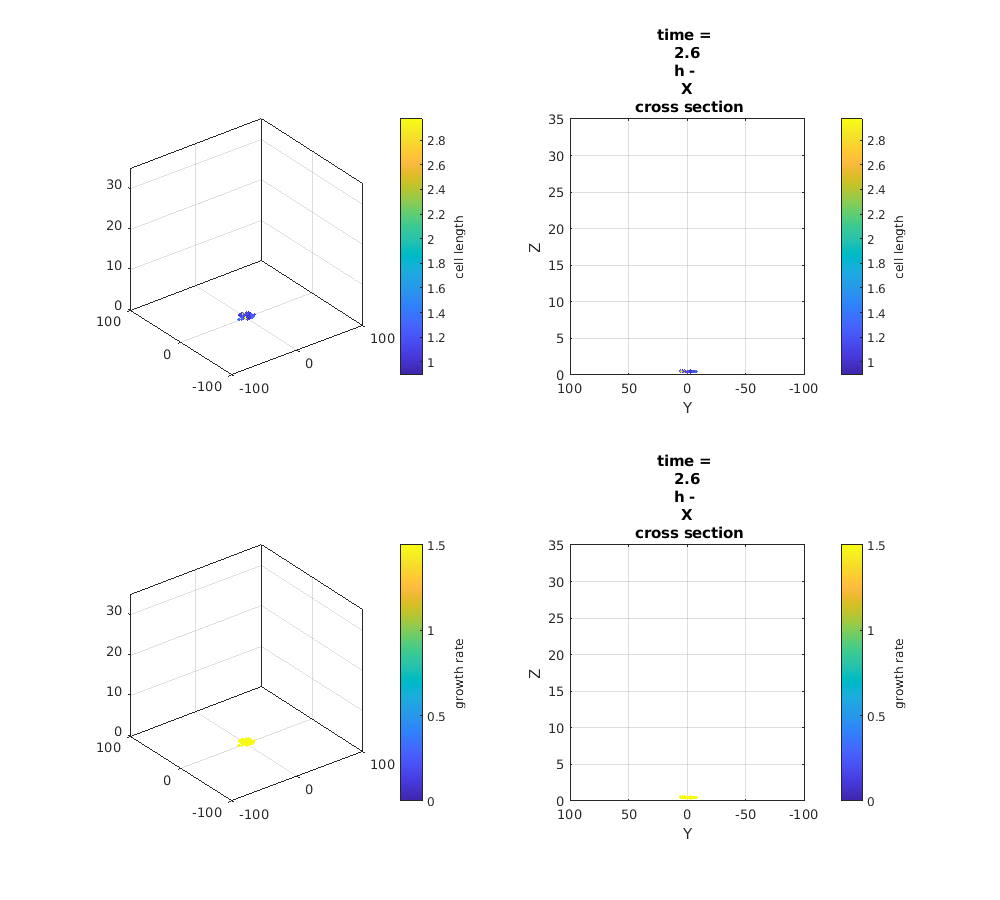

filepath  = [filepath,filesep,myfolder]; 

num_sim =  4;
cut_axis = "X";
cut_value =0;

for i_cells = 1:118
    for n = 1:num_sim
        file_path = sprintf('outputs/%s/Cells%d/%d.txt',data_set,n,i_cells);
        if n == 1
            cells = importdata(file_path);
        else
            cells = cat(1,cells,importdata(file_path));
        end
    end
    x1 = cells(:,4);
    x2 = cells(:,7);
    y1 = cells(:,5);
    y2 = cells(:,8);
    z1 = cells(:,6);
    z2 = cells(:,9);
    growth_rate = cells(:,17);
    
    % average co-ordinates
    x = (x1 + x2)/2;
    y = (y1 + y2)/2;
    z = (z1 + z2)/2;
    lengths = cells(:,10);
    pole_age_p = cells(:,27); % p age
    pole_age_q = cells(:,28); % q age
    pole_age_older = max(pole_age_p, pole_age_q);
    
    global thickness dot_size;
    dot_size =4;
    thickness =10;
    figure('Position', [100 0 1000 900])
    hold on;
    subplot(2,2,1)
    plt.color_scatter(x,y,z,dot_size,lengths,"cell length");
    subplot(2,2,2)
    plt.color_scatter(x,y,z,dot_size,lengths, "cell length",cut_axis,cut_value);
    subplot(2,2,3)
    plt.color_scatter(x,y,z,dot_size,growth_rate, "growth rate");
    caxis([0 1.5]);
    subplot(2,2,4)
    plt.color_scatter(x,y,z,dot_size,growth_rate, "growth rate",cut_axis,cut_value);
    caxis([0 1.5]);
    hold off;
    temp=[filepath,filesep,'fig',num2str(i_cells),'.png'];

    saveas(gca,temp);
end